%% Requires anakin in your Matlab path (https://github.com/uc3m-aerospace/anakin)

clearvars
close all
clc

## Reference frame S0 (inertial)

% Reference frame S0
O = anakin.point;
B0 = anakin.basis;
S0 = anakin.frame(O,B0);

## Rigid body definition

% Declare symbolic variables
syms t x(t) y(t) z(t) psi(t) theta(t) phi(t);
assumeAlso(t,'real');
assumeAlso(x(t),'real');
assumeAlso(y(t),'real');
assumeAlso(z(t),'real');
assumeAlso(diff(x(t),t),'real');
assumeAlso(diff(y(t),t),'real');
assumeAlso(diff(z(t),t),'real');
assumeAlso(diff(x(t),t,t),'real');
assumeAlso(diff(y(t),t,t),'real');
assumeAlso(diff(z(t),t,t),'real');
assumeAlso(psi(t),'real');
assumeAlso(theta(t),'real');
assumeAlso(phi(t),'real');
assumeAlso(diff(psi(t),t),'real');
assumeAlso(diff(theta(t),t),'real');
assumeAlso(diff(phi(t),t),'real');
assumeAlso(diff(psi(t),t,t),'real');
assumeAlso(diff(theta(t),t,t),'real');
assumeAlso(diff(phi(t),t,t),'real');

% Center of mass of the rigid body
G = anakin.point([x,y,z]);

% 3-1-3 Euler angles and intermediate rotations
B1 = B0.rotatez(psi);
B2 = B1.rotatex(theta);
Bb = B2.rotatez(phi);

% Body-fixed reference frame Sb
Sb = anakin.frame(G,Bb);

% Box rigid body
m = 20; % mass [kg]
Lx = 0.5; % length [m]
Ly = 0.1; % width [m]
Lz = 0.2; % heigth [m]
b = anakin.body.box(m,G,Bb,Lx,Ly,Lz);

## External force and torque about G

% Resultant force and torque about G
F = anakin.tensor([0,0,0]);
MG = anakin.tensor([0,0,0]);

## Fixed G: Integration of equations of motion

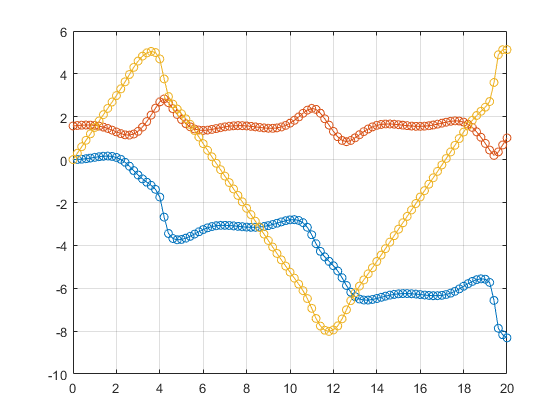

b = b.subs({x,y,z},{0,0,0});
HG0 = b.H(G,S0);
w = b.omega;
eqs = b.equations(F,G,MG,S0);
eqs = eqs(4:6);
vars = [psi;theta;phi];

[eqs, vars] = reduceDifferentialOrder(eqs, vars);
fun = daeFunction(eqs,vars);

% Initial conditions for ode15i
Y0est = [0,pi/2,0,0,0.1,1.5];
YP0est = [0.1,0,0,0,0,0];
options = odeset('RelTol', 1e-7, 'AbsTol' , 1e-7);
[Y0, YP0] = decic(fun, 0, Y0est, [], YP0est, [], options);

[t_,y_] = ode15i(fun,[0:0.2:20],Y0,YP0,options);
f1 = figure;
plot(t_,y_(:,1:3),'-o');
grid on;

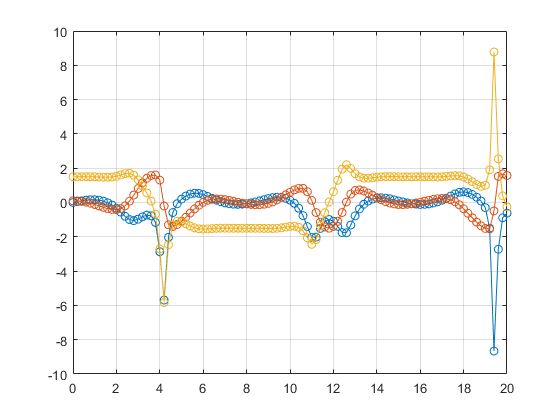

f2 = figure;
plot(t_,y_(:,4:6),'-o');
grid on;

## Time movie

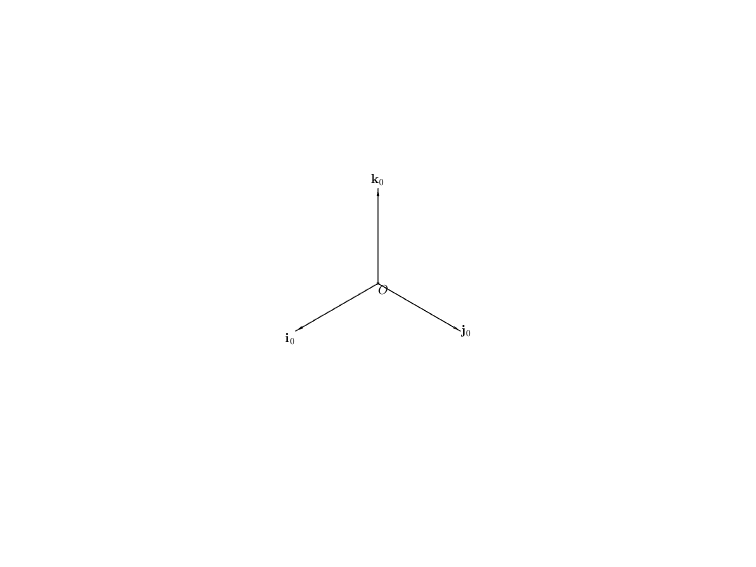

if 1==1 % activate if you want the movie
    
    % Prepare scene
    f3 = figure;
    f3.Units = 'centimeters';
    f3.Position = [1,1,20,15];
    a = axes;
    a.Units = 'centimeters';
    a.Position = [0,0,20,15];
    a.DataAspectRatio = [1,1,1];
    a.XTick = [];
    a.YTick = [];
    a.ZTick = [];
    a.XLim = [-1.5,1.5];
    a.YLim = [-1.5,1.5];
    a.ZLim = [-1.5,1.5];
    a.XAxis.Visible = 'off';
    a.YAxis.Visible = 'off';
    a.ZAxis.Visible = 'off';
    a.CameraPosition = [2,2,2];
    a.CameraTarget = [0,0,0];
    a.CameraViewAngle = 70;
    light;
    
    % Plot S0
    S0.plot;
    S0.plotlabel({'O','\mathbf i_0','\mathbf j_0','\mathbf k_0'});
    
    % Values of the variables for each instant of time
    psi_ = y_(:,1);
    theta_ = y_(:,2);
    phi_ = y_(:,3);
    dpsi_ = y_(:,4);
    dtheta_ = y_(:,5);
    dphi_ = y_(:,6);
    
    % Prepare each frame
    FF(length(t_)) = struct('cdata',[],'colormap',[]);
    for i = 1:length(t_)
        b_ = b.subs({psi,theta,phi},{psi_(i),theta_(i),phi_(i)});
        HG0_ = HG0.subs({diff(psi(t),t),diff(theta(t),t),diff(phi(t),t)},{dpsi_(i),dtheta_(i),dphi_(i)});
        HG0_ = HG0_.subs({psi,theta,phi},{psi_(i),theta_(i),phi_(i)});
        w_ = w.subs({diff(psi(t),t),diff(theta(t),t),diff(phi(t),t)},{dpsi_(i),dtheta_(i),dphi_(i)});
        w_ = w_.subs({psi,theta,phi},{psi_(i),theta_(i),phi_(i)});
        hb_ = b_.plotbody('linestyle','none');
        hSb_ = b_.plot('color','r');
        hSbl_ = b_.plotlabel({'G','\mathbf i_b','\mathbf j_b','\mathbf k_b'},{},'color','r');
        hHG0_ = HG0_.plot('color',[0.5,0,0]);
        hHG0l_ = HG0_.plotlabel('\mathbf H_{G0}','','color',[0.5,0,0]); 
        hw_ = w_.plot('color',[0,0.5,0]);
        hwl_ = w_.plotlabel('\mathbf \omega_{b0}','','color',[0,0.5,0]);
        
        drawnow;
        FF(i).colormap = [];
        FF(i).cdata = print('-RGBImage','-r600');
        
        % Clear for next instant
        delete(hb_)
        delete(hSb_)
        delete(hSbl_)
        delete(hHG0_)
        delete(hHG0l_) 
        delete(hw_)
        delete(hwl_)         
    end
    v = VideoWriter('mymovie3','MPEG-4');
    v.FrameRate = 10;
    v.open;
    writeVideo(v,FF);
    v.close;
end